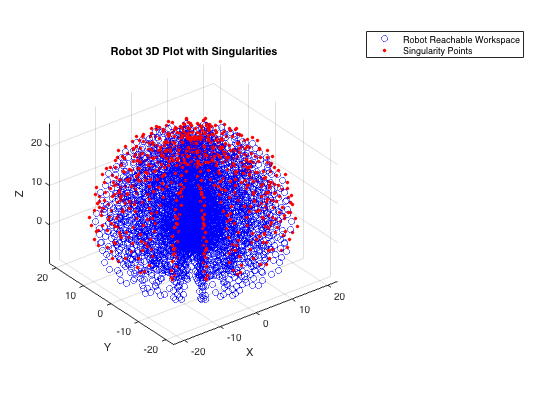

clc;
clear;
syms d1 L1 L2 L3 theta1 theta2 theta3 theta4 theta5

% Define transformation matrices
T01 = DistalDH([0 pi/2 d1 theta1]);
T12 = DistalDH([L1 0 0 theta2]);
T23 = DistalDH([L2 0 0 theta3]);
T34 = DistalDH([0 pi/2 0 theta4]);
T45 = DistalDH([0 0 L3 theta5]);
T05 = T01 * T12 * T23 * T34 * T45;

% Extract x, y, z positions from T04
x = T05(1,4);
y = T05(2,4);
z = T05(3,4);

% Convert symbolic expressions to MATLAB functions for numerical evaluation
f_x = matlabFunction(x, 'Vars', {d1, L1, L2, L3, theta1, theta2, theta3, theta4, theta5});
f_y = matlabFunction(y, 'Vars', {d1, L1, L2, L3, theta1, theta2, theta3, theta4, theta5});
f_z = matlabFunction(z, 'Vars', {d1, L1, L2, L3, theta1, theta2, theta3, theta4, theta5});

% Define parameters
L1_val = 10; % Length of link 1
L2_val = 10; % Length of link 2
L3_val = 3;
d1_val = 3;
psi = theta2 + theta3 + theta4;
u = theta5;
angle = deg2rad(360);

% Define ranges for joint variables
theta1_vals = linspace(0, angle, 10);
theta2_vals = linspace(0, pi, 10);
theta3_vals = linspace(0, angle, 10);
theta4_vals = linspace(0, angle, 10);
theta5_vals = linspace(0, angle, 10);

% Compute points to plot robot arm and singularity positions
x_vals = [];
y_vals = [];
z_vals = [];
psi_vals = [];
u_vals = [];

singularity_x_vals = [];
singularity_y_vals = [];
singularity_z_vals = [];

% Define the Jacobian matrix and calculate its determinant
J = [diff(x,theta1) diff(x,theta2) diff(x,theta3) diff(x,theta4) diff(x,theta5);
     diff(y,theta1) diff(y,theta2) diff(y,theta3) diff(y,theta4) diff(y,theta5);
     diff(z,theta1) diff(z,theta2) diff(z,theta3) diff(z,theta4) diff(z,theta5);
     diff(psi,theta1) diff(psi,theta2) diff(psi,theta3) diff(psi,theta4) diff(psi,theta5);
     diff(u,theta1) diff(u,theta2) diff(u,theta3) diff(u,theta4) diff(u,theta5)];

%JJt = simplify(J * J.');  % Jacobian multiplied by its transpose
T = simplify(det(J));   % Determinant of JJ^T

solve (T == 0);


%Create a function for T to calculate singularities numerically
f_T = matlabFunction(T, 'Vars', {d1, L1, L2, L3, theta1, theta2, theta3, theta4, theta5});

% Loop through joint values and evaluate positions and singularities
for theta1_val = theta1_vals
    for theta2_val = theta2_vals
        for theta3_val = theta3_vals
            for theta4_val = theta4_vals
                for theta5_val = theta5_vals
                    % Compute position
                    x_val = f_x(d1_val, L1_val, L2_val, L3_val, theta1_val, theta2_val, theta3_val, theta4_val, theta5_val);
                    y_val = f_y(d1_val, L1_val, L2_val, L3_val, theta1_val, theta2_val, theta3_val, theta4_val, theta5_val);
                    z_val = f_z(d1_val, L1_val, L2_val, L3_val, theta1_val, theta2_val, theta3_val, theta4_val, theta5_val);
                    
                    % Evaluate determinant of Jacobian
                    T_val = f_T(d1_val, L1_val, L2_val, L3_val, theta1_val, theta2_val, theta3_val, theta4_val, theta5_val);

                    % Check if determinant is NOT a singularity
                    if abs(T_val) > 1e-6 && all(imag(T_val) == 0)  % Adjust threshold for numerical stability
                        % Save non-singular points
                        x_vals = [x_vals, x_val];
                        y_vals = [y_vals, y_val];
                        z_vals = [z_vals, z_val];
                    else
                        % Save singular points only
                        singularity_x_vals = [singularity_x_vals, x_val];
                        singularity_y_vals = [singularity_y_vals, y_val];
                        singularity_z_vals = [singularity_z_vals, z_val];
                    end
                end
            end
        end
    end
end


% Plot the robot's reachable workspace
figure;
plot3(x_vals, y_vals, z_vals, 'bo'); % Plot all reachable points in blue
hold on;

% Plot singularity points in red
plot3(singularity_x_vals, singularity_y_vals, singularity_z_vals, 'ro', 'MarkerSize', 3, 'MarkerFaceColor', 'r');
legend('Robot Reachable Workspace', 'Singularity Points');
% legend('Robot Reachable Workspace');

xlabel('X');
ylabel('Y');
zlabel('Z');
title('Robot 3D Plot with Singularities');
% title('Robot 3D Plot');
grid on;
axis equal;